# Vogel_Max_AccelerationInFreeFall.mlx

*Max Vogel, Alec Messman, Eric Haag, and Sam Jerabek*

**Goal: **To calculate the aceeleration caused by gravity

### Importing Data

clear;
dataTb = readtable("data_set_1\data.csv");
dot = dataTb{:,1};

Because the last two data points are outliers (perhaps because the object falling came in contact with the ground, thus gravity was no longer applying a force to it?), we will choose to discard them.

We'll also devide each value by 100 to convert from cm to meters.

set11 = dataTb{1:end-1,2} / 100;
set12 = dataTb{1:end-1,3} / 100;

### Setting up Constants

n = max(length(set11), length(set12));
h = 2; % drop height in m
g = 9.803636; % acceleration of gravity in Chamberlin Hall
tmax = sqrt(2*h/g); % maximum time (s)
f = 60; % spark generator frequency (Hz)
dt = 1/f; % time interval between sparks (s)
t = (0:dt:dt*(n-1))'; % spark times

### Cleaning up data

We'll zero our data so they both start at, well, zero!

To do this, we'll grab the start of of each vector, and subtract each data set from it.

set11Start = set11(1, 1);
set11 = set11 - set11Start;

set12Start = set12(1, 1);
set12 = set12 - set12Start;

### Compare with Histogram

We'll subtract the two vectors and dispaly the result with a histogram.

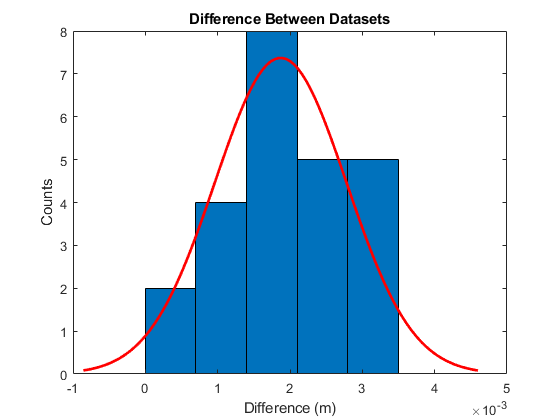

difference = (set12 - set11);
histfit(difference, 5)
xlabel('Difference (m)'); ylabel('Counts'); title('Difference Between Datasets');

### Generating Data Information

mean = mean(difference)

mean = 0.0019

std = std(difference)

std = 9.0912e-04

Our standard deviation is ~9/10 of a milimeter, so our data is looking good and we don't have any noticible outliers.

We can go ahead and generate the average position of each dot now:

avg = zeros(n, 1); % preallocate/fill

for i=1:n
    avg(i) = (set11(i)+set12(i)) / 2;
end

### Plotting

We'll go ahead and plot the time versus the displacement as such:

stdVector = std*ones(n,1); % estimated position error vector

errorbar(t, avg, stdVector);
title('Position versus Time'); xlabel('Time (s)'); ylabel('Displacement (m)'); 

We'll also change y-axis to start at 0 for *aesthetics* 

curYLim = ylim; % get the current Y limits
ylim([0 curYLim(2)]) % change the lower limit

### Fit our data to Polynomial

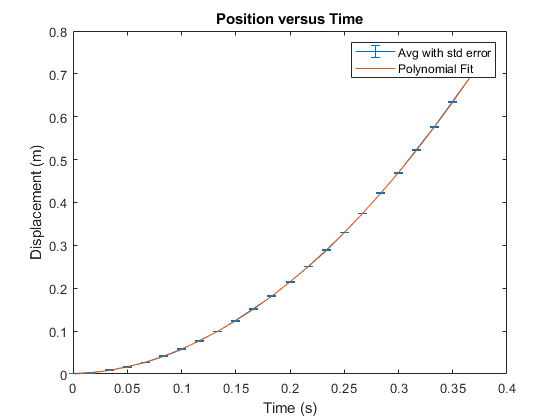

hold on; % lets us keep drawing to graph
degree = 2; % the degree of the polynomial
[P,S] = polyfit(t, avg, degree); % fit for polynominal 
Y = polyval(P, t); % compute poloynomial at times
plot(t, Y) % superpose on plot of original points
legend('Avg with std error', 'Polynomial Fit');
hold off;


### Residual Plots

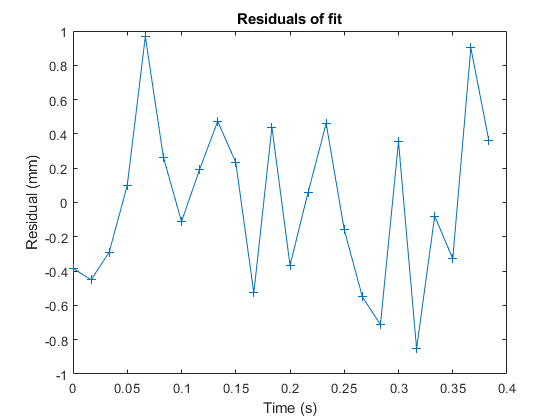

residuals = Y-avg; % differences between fit and data
figure % we want a new figure for this; different scale
plot(t, residuals*1000, '+-'); title('Residuals of fit');
xlabel('Time (s)'); ylabel('Residual (mm)')% note scale change

We can see that there are no visible trends.

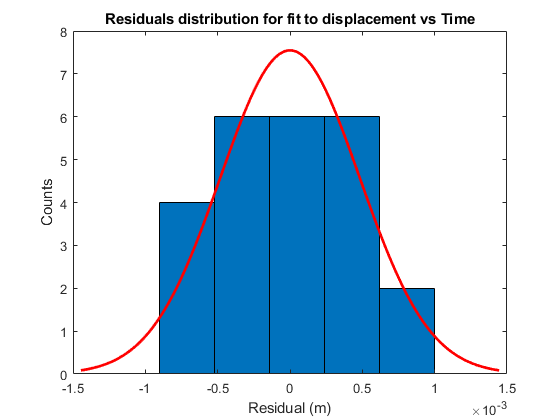

histfit(residuals, 5)
title('Residuals distribution for fit to displacement vs Time')
xlabel('Residual (m)');ylabel('Counts')

Since we already eliminated the ending points at the very beggining and because we don't have any other outliers, our histogram of residuals looks like a normal distribution.

### Estimating Gravity

We can reference the template to calculate our estimated gravity value.

First, we'll get "*S, the matrix R, the number of degrees of freedom df, and the norm of the residuals (of the deviations between fit and data)*"

R=S.R; df=S.df;normr=S.normr;

Next, "w*e then compute the inverse Rinv of the matrix R to estimate the covariance matrix Cov*"

Rinv=inv(R); Cov = (Rinv*Rinv')*normr^2/df;

Finally, "t*he diagonal elements of Cov are the estimates of the standard variances (std^2 ) of the parameters and the standard deviations (std's) are the square roots of these so we use *`diag`* to get the diagonal elements of Cov and take the square root of all of them using .^ as follows"*

stdHistFit=(diag(Cov)).^(1/2);

Which lets us find our estimated gravity value as well as it's standard deviation (error)

g_estimate = 2*P(1)

g_estimate = 9.8223

g_estimate_std = 2*stdHistFit(1)

g_estimate_std = 0.0173

### Group Gravity

We'll take our group data and average it. We'll assume that the standard deviation we calculated can be used for the rest of our group member's data too.

% Placeholder value = pi^2
g_eric = pi^2;
g_alec = pi^2;
g_sam = 9.7980;

g_group = (g_estimate + g_eric + g_alec + g_sam)/4

g_group = 9.8399

std_g_group = g_estimate_std/sqrt(4)

std_g_group = 0.0087

g_group_extra = ((g_estimate/g_estimate_std^2)+(g_eric/g_estimate_std^2)+(g_alec/g_estimate_std^2)+(g_sam/g_estimate_std^2))/(4*(1/g_estimate_std^2))

g_group_extra = 9.8399